% Describing the DH parameters for each link
L(1) = Link([pi/4  0.615 0.10 -pi/2]);
L(2) = Link([3.14  0 0.750 0]);
L(3) = Link([0 0 0.135 -pi/2 ]);
L(4) = Link([0 0.755 0 pi/2 ]);
L(5) = Link([pi/6 0 0 -pi/2]);
L(6) = Link([3.14 0.085 0 0]);

% connecting the links
robot = SerialLink(L);
robot.name = 'ABB IRB 2400'

 
robot = 
 
ABB IRB 2400:: 6 axis, RRRRRR, stdDH, slowRNE                    
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.615|        0.1|    -1.5708|          0|
|  2|         q2|          0|       0.75|          0|          0|
|  3|         q3|          0|      0.135|    -1.5708|          0|
|  4|         q4|      0.755|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|      0.085|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


% initializing cordiantes of center
x=0;
y=0;
r=0.1;
sample= 8;
sample_1 = sample - 1;
th = 0:(pi*2)/sample_1:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
x_ = xunit;
y_ = yunit;
[m,n] = size(xunit);
sample_ = n;
z_ = zeros(1,sample_);
cir = [x_;y_;z_];
cir_ = cir';

Now, we need to rotate and translate the points and store them.

% rotate created circle
xrot = 0;
yrot = 30;
zrot = 35;
% Move all points by x,y,z 
xmove = 0.25;
ymove = 0;
zmove = 0.4;

% Creating the rotation matrix 
T=rpy2r(xrot,yrot,zrot,'deg');
for i=1:sample_ 
    dotMap(i,:)=cir_(i,:)*T;
end
dotMap;

for i=1:sample_
    cir3(i,1)= dotMap(i,1)+xmove;
    dotMap(i,1) = cir3(i,1);
end
 dotMap;

for i=1:sample_
    cir3(i,2)= dotMap(i,2)+ymove;
    dotMap(i,2) = cir3(i,2);
end
 dotMap;

for i=1:sample_
    cir3(i,3)= dotMap(i,3)+zmove;
    dotMap(i,3) = cir3(i,3);
end
 dotMap;


The number of steps in the trajectory m is a function of the number of via points and the time or velocity limits that apply.

% starting from the first point of dotMap
start = dotMap(1,:);
time_step = 0.02;

x = mstraj(dotMap,[0.07 0.07 0.07],[],start,time_step,0);
[m,n] = size(x);

As we can see we have "m" points in our movement 

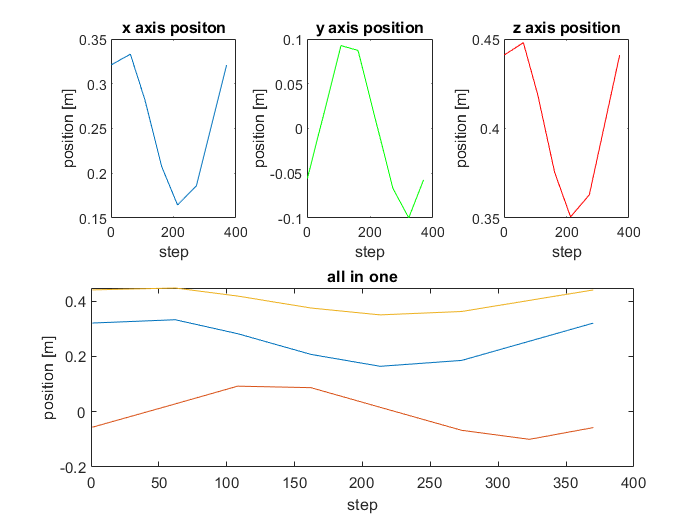

HG_matrix = zeros(4,4,m);
J_angles = zeros(m,6);
J_speed = zeros(m,6);

for i = 1:m
    for j = 1:3
    if x(i,j) < 1e-7 && x(i,j) > -1e-7
       x(i,j) = 0;
    end
    end
end

%Creating multiple plots
figure (1)
subplot(2,3,1)
plot(x(:,1))
title('x axis positon')
xlabel('step')
ylabel('position [m]')

subplot(2,3,2)
plot(x(:,2),'color','g')
title('y axis position')
xlabel('step')
ylabel('position [m]')

subplot(2,3,3)
plot(x(:,3),'color','r')
title('z axis position')
xlabel('step')
ylabel('position [m]')


%total time taken in seconds
total_time = time_step * m

total_time = 7.4000

Calculating the speeds

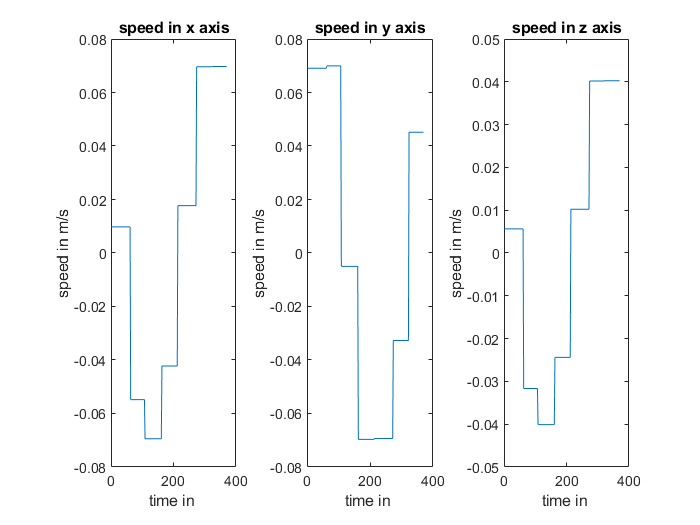

x_dot = gradient(x(:,1)/time_step);
y_dot = gradient(x(:,2)/time_step);
z_dot = gradient(x(:,3)/time_step);

figure(2)
clf
subplot(1,3,1)
plot(x_dot)
title('speed in x axis')
xlabel('time in ')
ylabel('speed in m/s')

subplot(1,3,2)
plot(y_dot)
title('speed in y axis')
xlabel('time in ')
ylabel('speed in m/s')

subplot(1,3,3)
plot(z_dot)
title('speed in z axis')
xlabel('time in ')
ylabel('speed in m/s')